### Pérdidas en el hierro (ensayo de vacío)

% Datos
Vo = [50, 100, 150, 200, 220, 240];
Po = [0.8, 2.8, 5.9, 10.3, 12.4, 14.9];

p1 = polyfit(Vo, Po, 2)

p1 =     0.0003   -0.0004    0.2198


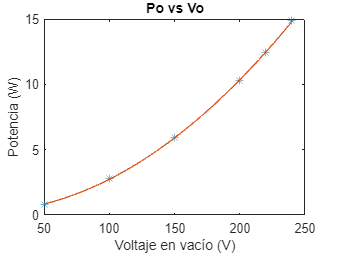

Vo_fit = linspace(min(Vo), max(Vo), 100);
Po_fit = polyval(p1, Vo_fit);

plot(Vo, Po, '*');
hold on;
plot(Vo_fit, Po_fit);
hold off;
title('Po vs Vo');
xlabel('Voltaje en vacío (V)');
ylabel('Potencia (W)');

### Pérdidas en el hierro (ensayo de vacío)

% Datos
Icc = [1, 2, 3, 4, 4.5, 5];
Pcc = [1.9, 8.6, 17.7, 31.7, 40.4, 49.1];  

p2 = polyfit(Icc, Pcc, 2)

p2 =     1.8849    0.4937   -0.3442


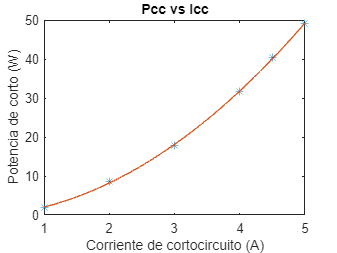

Icc_fit = linspace(min(Icc), max(Icc), 100);
Pcc_fit = polyval(p2, Icc_fit);

plot(Icc, Pcc, '*');
hold on;
plot(Icc_fit, Pcc_fit);
title('Pcc vs Icc');
xlabel('Corriente de cortocircuito (A)');
ylabel('Potencia de corto (W)');